# Test of Neural Network

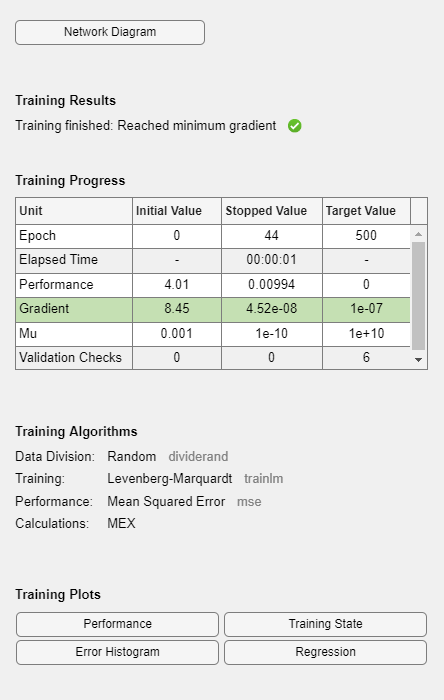

% net = network();
% view(net);
input_data = linspace(-5, 5, 1000);
output_data = sin(input_data) + 0.1 * randn(size(input_data));
input_data = con2seq(input_data);
output_data = con2seq(output_data);

net = feedforwardnet(10);
% net.inputs{1}
% net.layers{1}
% net.layers{2}
% net = configure(net, input_data, output_data);
net.divideParam.trainRatio = 0.8;
net.divideParam.testRatio = 0.2;
net.trainParam.epochs = 500;
net.trainParam.mu = 0.001;
net = train(net, input_data, output_data);

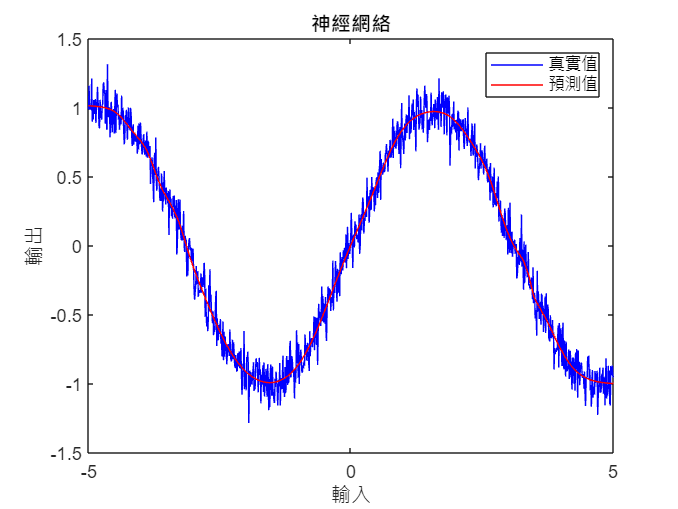


test_input = con2seq(linspace(-5, 5, 100));
predicted_output = sim(net,test_input);

input_data = cell2mat(input_data);
output_data = cell2mat(output_data);
test_input = cell2mat(test_input);
predicted_output = cell2mat(predicted_output);

figure;
plot(input_data, output_data, 'b', test_input, predicted_output, 'r');
legend('真實值', '預測值');
xlabel('輸入');
ylabel('輸出');
title('神經網絡');